# **Project 2 - Effectivness of Not Switching Classrooms**

**By Michaela Fox and Elisa Camacho**

## **Question**

Our modeling question is does having students stay in one classroom reduce the number of students that get the common cold as opposed to having students switch classrooms like in most schools? This is a design question because we are trying to design a way of arranging students that decreases the number of people infected with the common cold.

pod20 = ones(20,20) - eye(20);
zeros20 = zeros(20,20);
finalmatrix = [
    pod20 zeros20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 pod20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 pod20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 pod20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 pod20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 pod20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 zeros20 pod20]

finalmatrix =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     1     1     1     

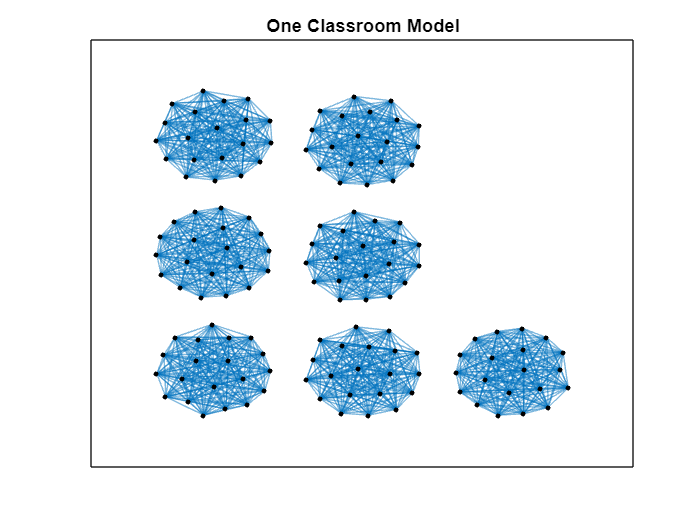

graph20pod = graph(finalmatrix);
figure();
h = plot(graph20pod, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('One Classroom Model')

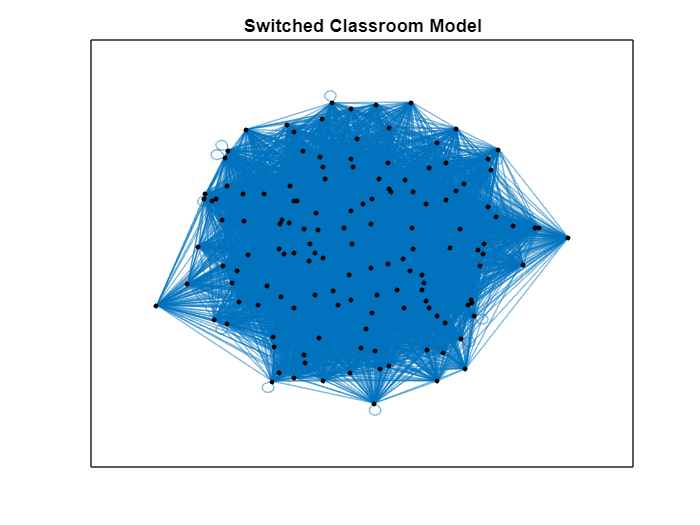

finalmatrix2 = finalmatrix;
rng(0,'twister');
for i = 1:5880
    p1 = randi([1 140]);
    p2 = randi([1 140]);
    finalmatrix2(p1,p2) = finalmatrix2(p1,p2) + 1;
    finalmatrix2(p2,p1) = finalmatrix2(p2,p1) + 1;
end
graph20pod2 = graph(finalmatrix2);
figure();
h = plot(graph20pod2, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('Switched Classroom Model')

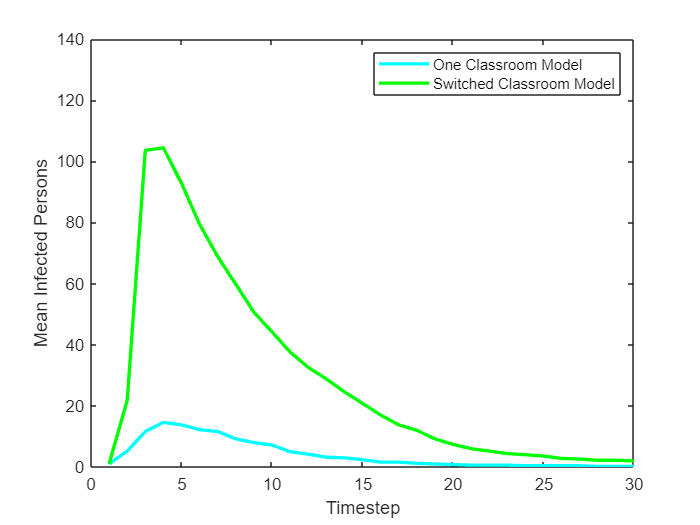

%Simulate one classroom model
infectionrate = 0.324;
recoveryrate = 0.143;
iv0 = zeros(140,1);
iv0(1) = 1;
timesteps = 30;
realizations = 5;
simresults1 = zeros(timesteps, realizations);
simresults2 = zeros(timesteps, realizations);
for i = 1:realizations
    [sho,iho,rho] =  simulate_absir(finalmatrix, iv0, timesteps, infectionrate, recoveryrate);
    simresults1(:, i) = sum(iho, 1);
end
%Simulate switched classroom model
for s = 1:realizations
    [shs,ihs,rhs] =  simulate_absir(finalmatrix2, iv0, timesteps, infectionrate, recoveryrate);
    simresults2(:,s) = sum(ihs,1);
end
meano = mean(simresults1, 2);
means = mean(simresults2, 2);
%icounto = sum(iho,1);
%icounts = sum(ihs,1);
figure()
plot(meano, 'c-', 'LineWidth', 2.0, 'DisplayName', 'One Classroom Model');
xlabel('Timestep')
ylabel('Mean Infected Persons')
ylim([0 140])
legend() 
hold on;
plot(means, 'g-', 'LineWidth', 2.0, 'DisplayName', 'Switched Classroom Model');